# 3D Genetic FIS Conflict Resolution Algorithm for UAVs

tic;
clc;
clear;
close all;

## Initialization

### Run Pre-req files

run simulation_parameters.m
run thresholds.m
run env_pre_req.m
addpath('../obj_detection');
addpath('bestFIS');
addpath('scenarios');

### Initiate System

system = struct();
uav = struct();
fis_type = "GA";
switch fis_type
    case "Manual"
        fis = FIS_script();
    case "GA"
        bestfis_file = "bestfis15";
        load(bestfis_file,'best_fis')
        fis = best_fis;
end

### Checks

ca = true; % Toggle for CA (On/Off)
store = false; % Storing the results
display = false; % Display Time, and Action Progress

### Load Scenario

scenario  = "scenario9";
load(scenario, 'states0', 'target_states0');
Num_UAV = gpuArray(size(states0,1));
disp(Num_UAV)

     2



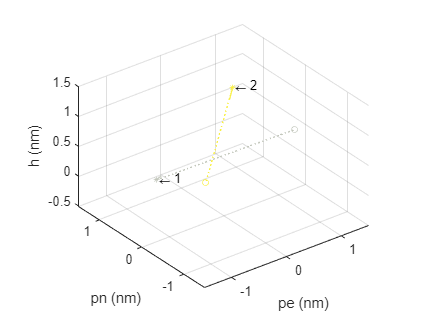

all = 1:Num_UAV;
uavs = gpuArray([1,2]); % Choose UAVs you want to process and plot
plot_system(states0(uavs,:),target_states0(uavs,:));

## Simulation of Collision Detection and Avoidance over each interval

Initiate Times and States for Simulation

ti = t0;
tf = 0.5;
t_inc = 0.5;
t_span = gpuArray(t0:t_inc:tmax);
ode_t_span = ti:dt:tf;
ode_t_range = gpuArray(1:size(ode_t_span,2));
t_span_range = gpuArray(1:size(t_span,2));
X0 = states0;
Yhist(:,:,1) = X0;
Thist(:,1) = t0;
flag = false;

for j = t_span_range
    if display, disp(t_span(j)); end
    system(j).uav_states = X0;
    system(j).uav_target_states = target_states0;
    system(j).int_sensing.count = 0; 
    system(j).int_sensing.id = [];
    system(j).int_sensing.states = [];
    system(j).coll_sensing.count = 0;
    system(j).coll_sensing.id = [];
    system(j).coll_sensing.states = [];
    system(j).colliding_uavs.id = [];
    system(j).colliding_uavs.states = [];
    system(j).collided_uavs.id = [];
    X0i = X0; % Same initial states for all UAVs for given time
    flag = false;
    
    for i = uavs
        % Ownship Initialization
        uav(i).states(j,:) = X0i(i,:);
        if j == 1
            uav(i).id = i;
            uav(i).states0 = states0(i,:);
            uav(i).target_states0 = target_states0(i,:);
            uav(i).dist_travelled = 0;            
            uav(i).min_coll_separation = [];
        end

        % Target, Desired, Other States Initialization
        uav(i).target_states(j,:) = target_states0(i,:);
        uav(i).des_states(j,:) = target_follower(uav(i).states(j,:),uav(i).target_states(j,:),th);
        system(j).uav(i).other_uavs.id = uavs(uavs~=i);
        system(j).uav(i).other_uavs.states = X0i(system(j).uav(i).other_uavs.id,:);
        
        % Intruder Sensing
        [int_states,int_id_return] = int_det(uav(i).states(j,:),...
            system(j).uav(i).other_uavs.states);

        if ~isempty(int_states)
            uav(i).int_sensed.status(j,:) = true;
            system(j).uav(i).int_sensed.count = size(int_states,1);
            system(j).uav(i).int_sensed.id = system(j).uav(i).other_uavs.id(int_id_return);
            system(j).uav(i).int_sensed.states = X0i(system(j).uav(i).int_sensed.id,:);
            system(j).int_sensing_uavs.count = system(j).int_sensing.count + 1;
            system(j).int_sensing_uavs.id = [system(j).int_sensing.id; ...
                uav(i).id];
            system(j).int_sensing_uavs.states = [system(j).int_sensing.states; ...
                uav(i).states(j,:)];

            % Signal UAV Sensed
            sen_text = string(uav(i).id) + " sensed " + ...
                        string(system(j).uav(i).int_sensed.id')...
                        + " sensed at " + string(t_span(j)) + " sec.";
            if display, disp(sen_text); end

            % Collision Estimation
            [coll_rel_states, near_coll_rel_states, coll_id_return, near_coll_id_return] = ...
                coll_det(uav(i).states(j,:),system(j).uav(i).int_sensed.states,th);
            
            if ~isempty(near_coll_rel_states)
                uav(i).coll_sensed.status(j,:) = true;
                system(j).uav(i).coll_sensed.count = size(coll_rel_states,1);
                system(j).uav(i).coll_sensed.id = system(j).uav(i).int_sensed.id(coll_id_return);
                system(j).uav(i).coll_sensed.states = X0i(system(j).uav(i).coll_sensed.id,:);
                system(j).uav(i).coll_sensed.rel_states = coll_rel_states;
                system(j).uav(i).near_coll_sensed.id = system(j).uav(i).coll_sensed.id(near_coll_id_return);
                system(j).uav(i).near_coll_sensed.states = X0i(system(j).uav(i).near_coll_sensed.id,:);
                system(j).uav(i).near_coll_sensed.rel_states = near_coll_rel_states;
                system(j).coll_sensing_uavs.count = system(j).coll_sensing.count + 1;
                system(j).coll_sensing_uavs.id = [system(j).coll_sensing.id; ...
                    uav(i).id];
                system(j).coll_sensing_uavs.states = [system(j).coll_sensing.states;...
                    uav(i).states(j,:)];
                system(j).colliding_uavs.id = [system(j).colliding_uavs.id, uav(i).id, ...
                    system(j).uav(i).coll_sensed.id];
                system(j).colliding_uavs.states = [system(j).colliding_uavs.states; uav(i).states(j,:); ...
                    system(j).uav(i).coll_sensed.states];
                
                % Signal Potential Collision
                coll_index = system(j).uav(i).coll_sensed.rel_states(:,14) == 1;
                coll_text = string(uav(i).id) + " in line for collision with " + ...
                            string(system(j).uav(i).coll_sensed.id(coll_index)')...
                            + " sensed at " + string(t_span(j)) + " sec.";
                if display, disp(coll_text); end

            else
                uav(i).coll_sensed.status(j,:) = false;
                system(j).uav(i).coll_sensed.count = 0;
                system(j).uav(i).coll_sensed.id = [];
                system(j).uav(i).coll_sensed.states = [];
                system(j).uav(i).near_coll_sensed.id = [];
                system(j).uav(i).coll_sensed.rel_states = [];
                system(j).uav(i).near_coll_sensed.id = [];
                system(j).uav(i).near_coll_sensed.states = [];
                system(j).uav(i).near_coll_sensed.rel_states = [];
            end

        else
            uav(i).int_sensed.status(j,:) = false;
            system(j).uav(i).int_sensed.count = 0;
            system(j).uav(i).int_sensed.id = [];
            system(j).uav(i).int_sensed.states = [];
            uav(i).coll_sensed.status(j,:) = 0;
            system(j).uav(i).coll_sensed.count = 0;
            system(j).uav(i).coll_sensed.id = [];
            system(j).uav(i).coll_sensed.states = [];
            system(j).uav(i).coll_sensed.rel_states = [];
            system(j).uav(i).near_coll_sensed.id = [];
            system(j).uav(i).near_coll_sensed.states = [];
            system(j).uav(i).near_coll_sensed.rel_states = [];

        end

        % Check for Collision
        [collision_check, coll_check_id_return] = coll_check(uav(i).states(j,:),...
            system(j).uav(i).other_uavs.states,th);

        % Stop at Collision
        if any(collision_check == 1)
            uav(i).collision.status(j,:) = true;
            system(j).uav(i).collided_uavs.id = system(j).uav(i).other_uavs.id(coll_check_id_return);
            system(j).uav(i).collided_uavs.states = X0i(system(j).uav(i).collided_uavs.id,:);
            system(j).collided_uavs.id = [uav(i).id,system(j).uav(i).collided_uavs.id];
            coll_check_text = string(uav(i).id) + " collided with " + ...
                        string(system(j).uav(i).collided_uavs.id)...
                        + " at " + string(t_span(j)) + " sec.";
            disp(coll_check_text)
            system(j).uav(i).coll_separation = sqrt(sum((system(j).uav(i).collided_uavs.states(:,1:3) ...
                - uav(i).states(j,1:3)).^2,2));
            uav(i).min_coll_separation = min([uav(i).min_coll_separation ; ...
                system(j).uav(i).coll_separation]);
            flag = true;
%             break;
        else
            flag = false;
            uav(i).collision.status(j,:) = false;
            system(j).uav(i).collided_uavs.id = [];
            system(j).collided_uavs.id = [];
            system(j).uav(i).coll_separation = [];
        end
        
        % Desired States
        des_states_check = uav(i).des_states(j,:);

        % Check if near Target States
        diff = abs([des_states_check(1), -des_states_check(2), des_states_check(3)] - X0i(i,[4,3,5]));
        uav(i).dist2target(j,:) = norm(uav(i).target_states(j,:) - uav(i).states(j,1:3));
        if j>=2
            uav(i).dist_travelled = uav(i).dist_travelled + norm(uav(i).states(j,1:3)-uav(i).states(j-1,1:3));
        end
%         disp(dist)

        % UAV Model and Control
        if uav(i).dist2target(j,:) > th.coll * th.DMOD
            [U,fis_o,k] = controller(uav(i).states(j,:), system(j).uav(i).near_coll_sensed.rel_states,...
                uav(i).des_states(j,:),fis,ca,th,g_nm);
            uav(i).command_states(j,:) = U;
            uav(i).fis_outputs(j,:) = fis_o;
            [Tout,Yout] = ode45(@(t,y) fw_uav(t,y,U,k,g_nm),ode_t_span,uav(i).states(j,:)');
            
        else % stop at destination/target
            uav(i).command_states(j,:) = NaN(1,5);
            Tout = ode_t_span;
            Yout = [repmat(X0(i,:),[length(Tout) 1])];%,NaN(length(Tout),5)];
        end
%         t_range = ode_t_range(end) + (1:length(Tout)-1);
%         Yhist(i,:,t_range) = Yout(1:end-1,:)';
%         Thist(i,t_range) = Tout(1:end-1)';
        X0(i,:) = Yout(end,:);
        Yhist(i,:,j+1) = X0(i,:);
        Thist(i,j) = t_span(j);
    end

    % Stop at Collision
    if flag
%         break;
    end
    ti = tf;
    tf = tf + t_inc;
    ode_t_span = ti:dt:tf;
    ode_t_range = 1:size(ode_t_span,2); 
end

## Cost Calculation

cost = 0;
penalty_x = 3000;
for i = uavs
    cost = cost + 1000*uav(i).dist_travelled + 10000*uav(i).dist2target(end,:);
    if any(uav(i).collision.status) && ca==1
        penalty_sep = penalty_x / uav(i).min_coll_separation;
        cost = cost + penalty_sep;
    end
end

##  Plot System, Paths

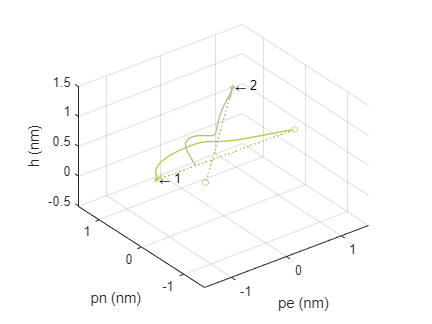

path = true; % Turn on or off
fig1 = plot_system(uav,uavs,path);

## Plot States

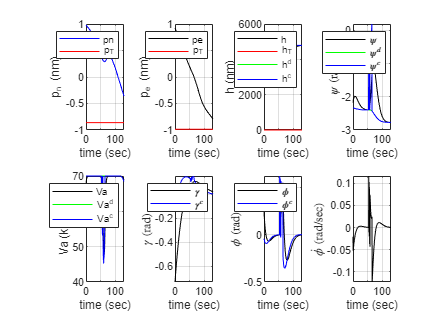

fig2 = plot_states(t_span,uav,i);
fig2.Position = [100 100 1080 800];

## Save files

if ca && fis_type == "GA"
    workspace_file = "results\"+ scenario + "_" + mat2str(uavs) + "_ca_" + bestfis_file;
    picture_title = "pictures\"+ scenario + "_" + mat2str(uavs) + "_ca_" + bestfis_file + ".png";
    plots_title = "pictures\"+ scenario + "_" + mat2str(uavs) + "_ca_" + bestfis_file + "_plots.png";
    video_title = "videos\"+ scenario + "_" + mat2str(uavs) +  "_ca_" + bestfis_file;
elseif ca && fis_type == "Manual"
    workspace_file = "results\"+ scenario + "_" + mat2str(uavs) +  "_ca_manual";
    picture_title = "pictures\"+ scenario + "_" + mat2str(uavs) +  "_ca_manual" + ".png";
    plots_title = "pictures\"+ scenario + "_" + mat2str(uavs) +  "_ca_manual" + "_plots.png";
    video_title = "videos\"+ scenario + "_" + mat2str(uavs) +  "_ca_manual";
else
    workspace_file = "results\"+ scenario + "_" + mat2str(uavs) +  "_nca";
    picture_title = "pictures\"+ scenario + "_" + mat2str(uavs) +  "_nca" + ".png";
    plots_title = "pictures\"+ scenario + "_" + mat2str(uavs) +  "_nca" + "_plots.png";
    video_title = "videos\"+ scenario + "_" + mat2str(uavs) +  "_nca";
end

## Animate UAV, Video Writer: initialize the video writer

animate = false; % Turn on or off animation
VIDEO = false;  % 1 means write video, 0 means don't write video

if animate, fig3 = animate_system(uav,uavs,VIDEO); end

## Storage

if store
    save(workspace_file); % Save Workspace
    saveas(fig1,picture_title); % Save Static System and Paths
    saveas(fig2,plots_title); % Save Plots
end

## Display Elapsed Time

toc;

Elapsed time is 6.253382 seconds.


disp(toc)

    6.2545

